## Matlab Error anaylsis

Error Anaylsis of follwing equation


$$\frac{1}{x}\ln\left(\frac{((1-R)^4+4T^2R^2)^{0.5} - (1-R)^2}{2T^2R^2}\right)$$


where b is the section within the ln

where 

x = R

x = 0.3100

y = T

y =     0.0027
    0.0027
    0.0028
    0.0028
    0.0029
    0.0030
    0.0029
    0.0028
    0.0027
    0.0027


z = 0.000417

z = 4.1700e-04


$$\frac{d}{dx}=\frac{x^2y^2\left(\frac{ \frac{8xy^2-4(1-x)^3}{2 \sqrt{4x^2y^2+(1-x)^4} }+2(1-x) }{2x^2y^2} -  \frac{ \sqrt{4x^2y^2+(1-x)^4}-(1-x)^2 }{x^3y^2}\right)}{z(\sqrt{4x^2y^2+(1+x)^4}-(1-x)^2)}$$
 

which in plain text is

dx = (2.*x.^2.*y.^2.*(((8.*x.*y.^2-4.*(1-x).^3)./(2.*sqrt(4.*x.^2.*y.^2+(1-x).^4)) +2.*(1-x))./(2.*x.^2.*y.^2) - (sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2)./(x.^3.*y.^2)))./(z.*sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2)

dx =    -0.1826
   -0.1826
   -0.1869
   -0.1963
   -0.2060
   -0.2210
   -0.2009
   -0.1866
   -0.1773
   -0.1727



$$\frac{d}{dy} = \frac{2x^2y^2\left(\frac{2}{y\sqrt{4x^2y^2+(1-x)^4}} - \frac{\sqrt{4x^2y^2+(1-x)^4}-(1-x)^2}{x^2y^3}\right)}{z(\sqrt{4x^2y^2+(1+x)^4}-(1-x)^2)}$$


dy = (2.*x.^2.*y.^2.*(((2)./(y.*sqrt(4.*x.^2.*y.^2+(1-x).^4)) - (sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2)./(x.^2.*y.^3)))./(z.*sqrt(4.*x.^2.*y.^2+(1-x).^4)-(1-x).^2))

dy =     0.1455
    0.1455
    0.1508
    0.1623
    0.1744
    0.1939
    0.1680
    0.1504
    0.1393
    0.1339



$$\frac{d}{dx} = \frac{1}{z^2}\ln\left(\frac{((1-R)^4+4T^2R^2)^{0.5} - (1-R)^2}{2T^2R^2}\right)$$


dz = ((1)./(z.^2)).*log((sqrt((1-R).^4+4.*T.^2.*R.^2)-(1-R).^2)./(2.*T.^2.*R.^2))

dz = 	1.0e+06 *

    4.2678
    4.2678
    4.2678
    4.2678
    4.2678
    4.2678
    4.2678
    4.2678
    4.2678
    4.2678


Errors of respective variables

% error on voltage
errVoltage = 0.001*ones(size(V0_1));
% error on Transmission Coefficient
%errT = 0.2*ones(size(V0_1))
errT = T.*(((errVoltage./V0_1).^2+(errVoltage./V1_1).^2).^0.5);
% error on R
errR = 0.01;
errz = 0.0001

errz = 1.0000e-04

errx = errR*ones(size(V0_1));
erry = errT;

err_alpha = sqrt((dx.*errx).^(2)+(dy.*erry).^(2)+(dz.*errz).^(2)+(dz.*errz).^(2));
% err_R_alpha = real(err_alpha);

err_B = err_alpha./alpha_GaAs

err_B =     0.0487
    0.0487
    0.0489
    0.0491
    0.0493
    0.0497
    0.0492
    0.0488
    0.0486
    0.0485


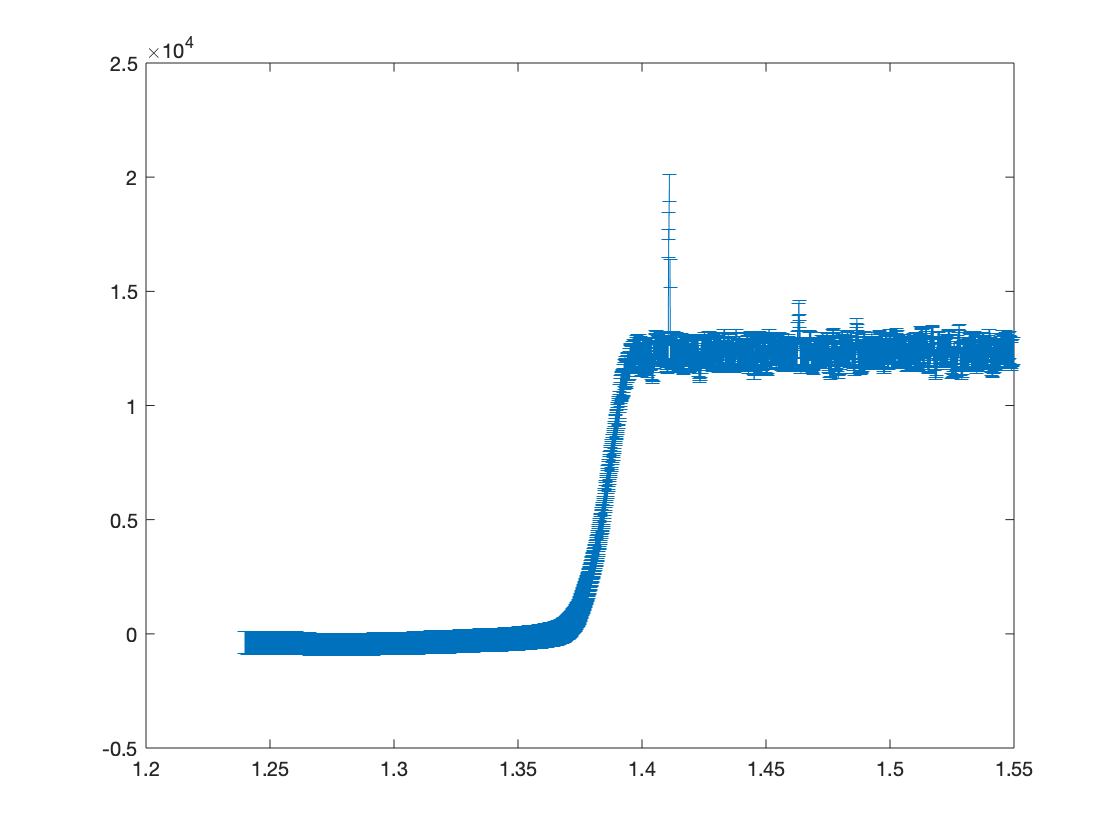


errorbar(eV_energy,alpha_GaAs,err_alpha,err_alpha)

 
% errorbar(wavelength,T,errT,errT)
 
% 5help_T = errT./T

help_alpha = (err_B./alpha_GaAs).*100

help_alpha = 	1.0e+04 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
